# Example 6.23: Kernel Estimation for Hougen-Watson Reaction

Note: this script reproduces Example 6.23 (Section 6.5) of **Statistics for Chemical Engineers**: a kernel model of the Hougen-Watson reaction rate for different kernel parameters gamma. Victor Z UW-Madison, 2020 predict Hougen-Watson reaction using kernel method

clc; clear all; close all hidden; format bank

% S = load('reaction');
% X = S.reactants % experimental reactant concentrations
% y = S.rate % experimental reaction rates
% beta = S.beta % guess for parameters

datar=load('Data/hougenwatson.dat');
X=datar(:,1:3); %partial pressures
y=datar(:,4);   % reaction rate

## Data

best guess for parameters

beta = [1.0000e+00
        5.0000e-02
        2.0000e-02
        1.0000e-01
        2.0000e+00];

[n,m]=size(X);

## Kernel models for different gamma

span gamma

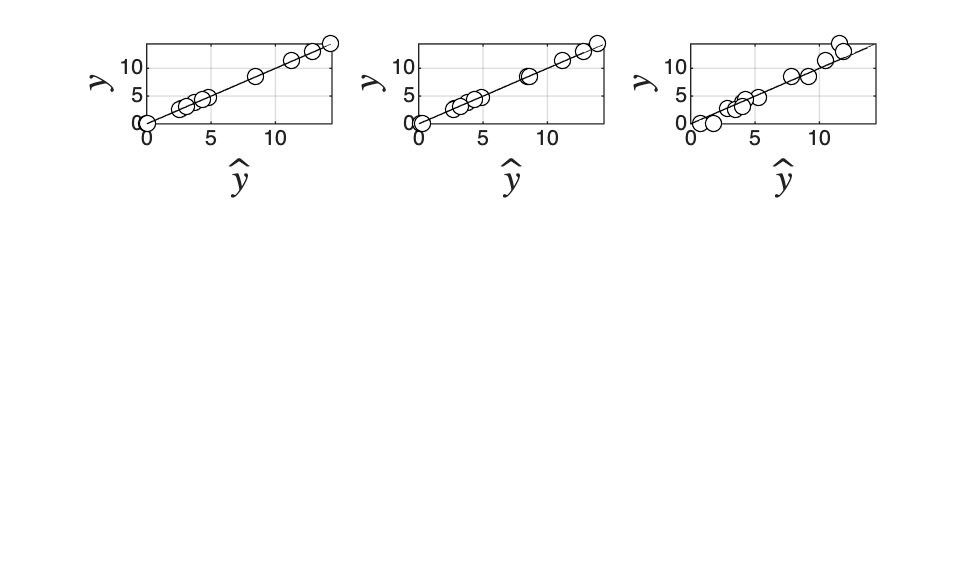

gamma=0.1;

for k=1:length(gamma)

% construct kernel matrix
for j=1:n
    for i=1:n
        K(i,j)=ker(X(i,:),X(j,:),gamma(k));
    end
end

% predict output 
lam=0.01;

yhat(:,k) = K*inv(K+lam*eye(n,n))*y;

SS(k)=norm(y-yhat(:,k)');

end

% plot prediction  and data
figure(1)
subplot(3,3,1)
plot(yhat,y,'blacko','MarkerFaceColor','w')
hold on
plot(y,y,'black--')
xlabel('$\hat{y}$','Interpreter','latex','Fontsize',14)
ylabel('$y$','Interpreter','latex','Fontsize',14)
grid on


% span gamma
gamma=0.001;

for k=1:length(gamma)

% construct kernel matrix
for j=1:n
    for i=1:n
        K(i,j)=ker(X(i,:),X(j,:),gamma(k));
    end
end

% predict output 
lam=0.01;
yhat(:,k) = K*inv(K+lam*eye(n,n))*y;

SS(k)=norm(y-yhat(:,k)');

end

% plot prediction  and data
figure(1)
subplot(3,3,2)
plot(yhat,y,'blacko','MarkerFaceColor','w')
hold on
plot(y,y,'black--')
xlabel('$\hat{y}$','Interpreter','latex','Fontsize',14)
ylabel('$y$','Interpreter','latex','Fontsize',14)
grid on

% span gamma
gamma=0.0001;

for k=1:length(gamma)

% construct kernel matrix
for j=1:n
    for i=1:n
        K(i,j)=ker(X(i,:),X(j,:),gamma(k));
    end
end

% predict output 
lam=0.01;
yhat(:,k) = K*inv(K+lam*eye(n,n))*y;

SS(k)=norm(y-yhat(:,k)');

end

% plot prediction  and data
figure(1)
subplot(3,3,3)
plot(yhat,y,'blacko','MarkerFaceColor','w')
hold on
plot(y,y,'black--')
xlabel('$\hat{y}$','Interpreter','latex','Fontsize',14)
ylabel('$y$','Interpreter','latex','Fontsize',14)
grid on


print -depsc ch6_hougen_fit_kernel.eps

## gaussian kernel function

function f=ker(x1,x2,gam)

f = exp(-gam*norm(x1-x2));

end

## Note

As in the book, the fit is rather insensitive to gamma, but it degrades for gamma = 0.0001: the kernel parameter must be tuned.